g = tf([1 20], [1 1.5 35])

g =
 
       s + 20
  ----------------
  s^2 + 1.5 s + 35
 
Continuous-time transfer function.
Model Properties


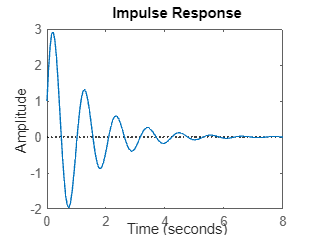


impulse(g)

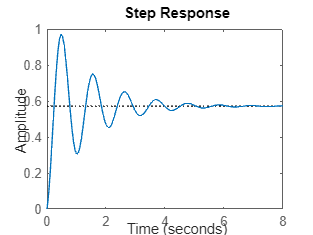

step(g)


T = 0.1

T = 0.1000


gd = c2d(g, T)

gd =
 
    0.18 z + 0.0003645
  ----------------------
  z^2 - 1.545 z + 0.8607
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


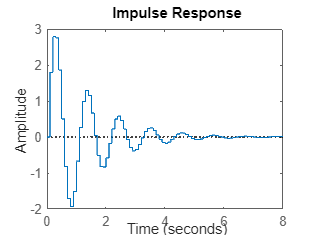


impulse(gd)

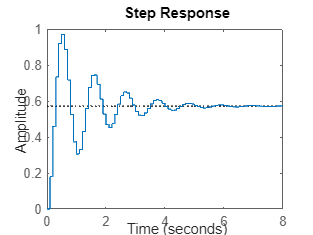

step(gd)

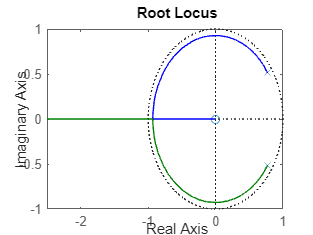


rlocus(gd)


%rltool(gd)

gdcont = gd*tf([1 0.3], [0.4 0], T)

gdcont =
 
  0.18 z^2 + 0.05437 z + 0.0001093
  --------------------------------
   0.4 z^3 - 0.618 z^2 + 0.3443 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


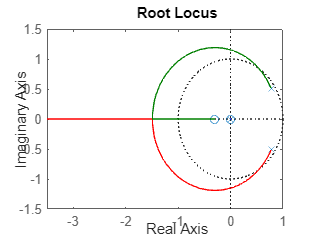


rlocus(gdcont)

%rltool(gdcont)

k = 9.0842

k = 9.0842